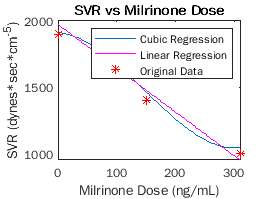

%%Plotting 2
clc;clear;
%%Plotting
a1=5.97e-05;
a2=-0.02631;
a3=-0.3797;
a4=1914;
x=linspace(0,310,100);
y=(a1.*x.^3)+(a2.*x.^2)+(a3.*x)+a4;
figure(1);
plot(x,y);
hold on
a5=-3.296;
a6=1975;
y1=(a5.*x) + a6;
plot(x,y1,'-m');
hold on
x1=[0 75 150 310];
y1=[1900 1825 1400 1000];
plot(x1,y1,'*r');
xlabel('Milrinone Dose (ng/mL)');
ylabel('SVR (dynes*sec*cm^{-5})');
title('SVR vs Milrinone Dose');
legend('Cubic Regression','Linear Regression','Original Data');
xlim([0 310]);
hold off

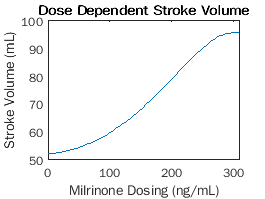

map=110;
cvp=10;
hr=80;
svr=y;
sv=((80*(map - cvp))./(hr.*svr))*1000;
figure(2);
plot(x,sv);
xlabel('Milrinone Dosing (ng/mL)');
ylabel('Stroke Volume (mL)');
title('Dose Dependent Stroke Volume');
xlim([0 310]);

equation1="SVR = 5.97e-05*X^3 - 0.02631*X^2 - 0.3797*X + 1914";
format short
displayFormula(equation1);

$$\mathrm{SVR}=0.0000597\,X^{3}-0.02631\,X^{2}-0.3797\,X+1914$$

equation2="SV=((80*(MAP - CVP))/(HR*SVR))*1000";
displayFormula(equation2);

$$\mathrm{SV}=\frac{80\,\left(\mathrm{MAP}-\mathrm{CVP}\right)}{\mathrm{HR}\,\mathrm{SVR}}\,1000$$